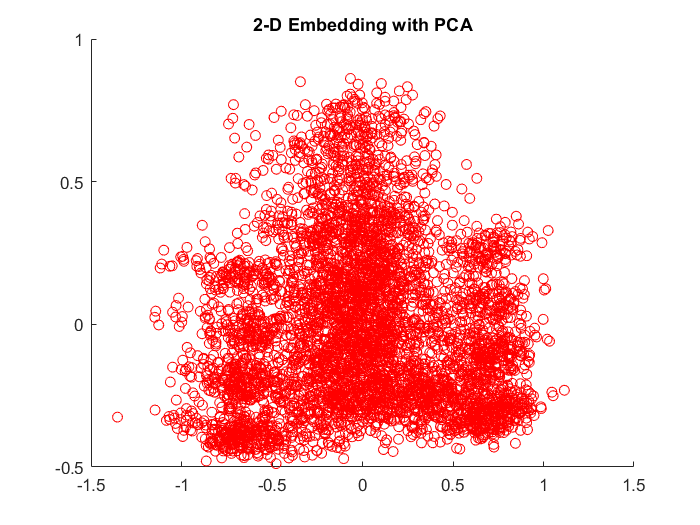

close all
clear all
clc

load('C:\Users\andre\Desktop\Magistrale\FINTECH\ZENTI\Progetto 1/BankClients.mat')

%
N = vartype('numeric');
Data = BankClients(:,2:end); % Exclude 1st col = ID
NumFeatures = Data(:,N); % subtable of numerical features
XNum = NumFeatures.Variables;

for i = 1:size(XNum,2)
XNum(:,i) = rescale(XNum(:,i)); % normalize in [0, 1], mostly unnecessary here (CHECK THIS)
end

% Categorical
C = vartype('categorical');
CatFeatures = Data(:,C); % subtable of categorical features

% Encoding (i.e. create dummy variables)
XCat = [];
for i = 1:size(CatFeatures, 2)
    XCat_i = dummyvar(grp2idx(CatFeatures{:,i}));
    XCat = [XCat XCat_i(:,1:end-1)]; 
end

X = XNum;

% nSubSample = 1950;
% rng('default') % for reproducibility
% randRows = randperm(size(X, 1), nSubSample);
% X = X(randRows', :);

[coeff,score,latent] = pca(X);
figure
scatter(score(:,1),score(:,2), 'r')
title('2-D Embedding with PCA')

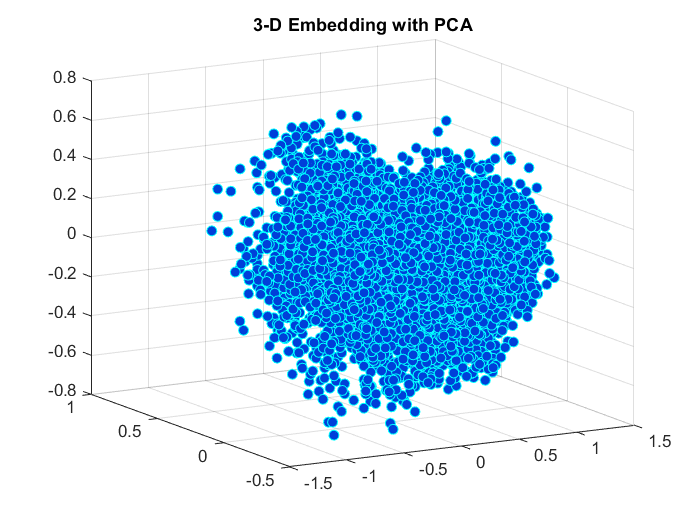

Y = [score(:,1), score(:,2), score(:,3)];
% 3D PCA
figure
scatter3(score(:,1),score(:,2),score(:,3),...
        'MarkerEdgeColor','c',...
        'MarkerFaceColor',[0 .25 .85])
title('3-D Embedding with PCA')
view(-30,15)

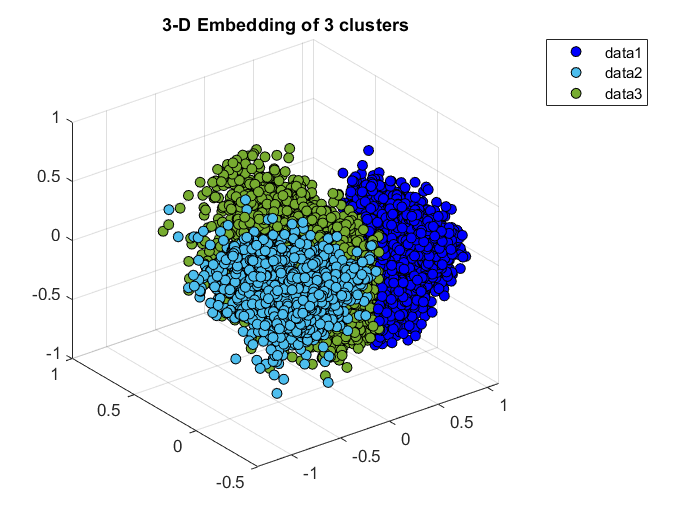


%% CLUSTERING 
% K == 3
rng('default')
[IDX3] = kmeans(X,3);

figure
scatter3(Y(IDX3==1,1),Y(IDX3==1,2),Y(IDX3==1,3),...
'MarkerEdgeColor','k',...
'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(IDX3==2,1),Y(IDX3==2,2),Y(IDX3==2,3),...
'MarkerEdgeColor','k',...
'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX3==3,1),Y(IDX3==3,2),Y(IDX3==3,3),...
'MarkerEdgeColor','k',...
'MarkerFaceColor',[0.4660 0.6740 0.1880])
title('3-D Embedding of 3 clusters')
legend
hold off

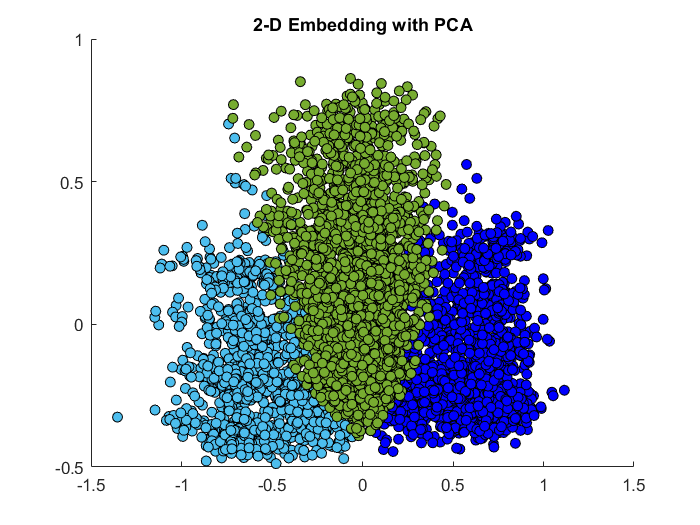


figure
scatter(Y(IDX3==1,1),Y(IDX3==1,2),...
'MarkerEdgeColor','k',...
'MarkerFaceColor',[0 0 1])
hold on
scatter(Y(IDX3==2,1),Y(IDX3==2,2),...
'MarkerEdgeColor','k',...
'MarkerFaceColor',[0.3010 0.7450 0.9330])
hold on 
scatter(Y(IDX3==3,1),Y(IDX3==3,2),...
'MarkerEdgeColor','k',...
'MarkerFaceColor',[0.4660 0.6740 0.1880])
title('2-D Embedding with PCA')

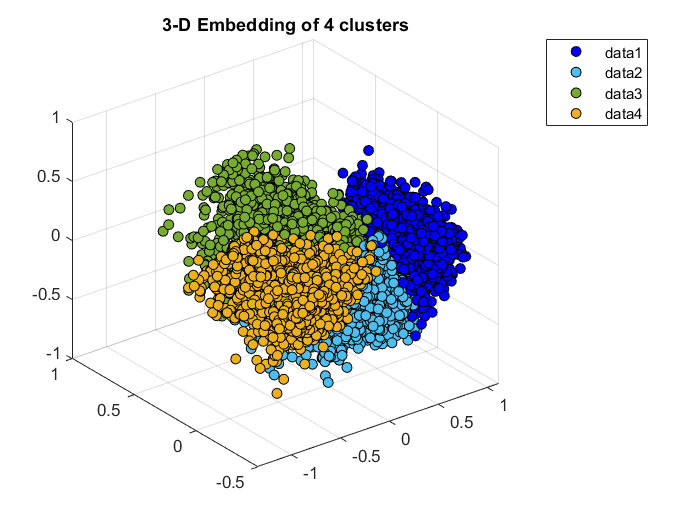



% K == 4
rng('default')
[IDX4] = kmeans(X,4);

figure
scatter3(Y(IDX4==1,1),Y(IDX4==1,2),Y(IDX4==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(IDX4==2,1),Y(IDX4==2,2),Y(IDX4==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX4==3,1),Y(IDX4==3,2),Y(IDX4==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
scatter3(Y(IDX4==4,1),Y(IDX4==4,2),Y(IDX4==4,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.9290 0.6940 0.1250])
title('3-D Embedding of 4 clusters')
hold off
legend

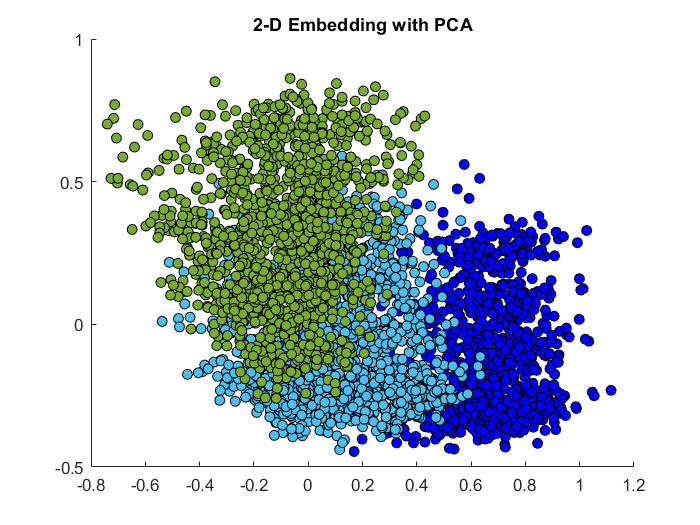


figure
scatter(Y(IDX4==1,1),Y(IDX4==1,2),...
'MarkerEdgeColor','k',...
'MarkerFaceColor',[0 0 1])
hold on
scatter(Y(IDX4==2,1),Y(IDX4==2,2),...
'MarkerEdgeColor','k',...
'MarkerFaceColor',[0.3010 0.7450 0.9330])
hold on 
scatter(Y(IDX4==3,1),Y(IDX4==3,2),...
'MarkerEdgeColor','k',...
'MarkerFaceColor',[0.4660 0.6740 0.1880])
title('2-D Embedding with PCA')

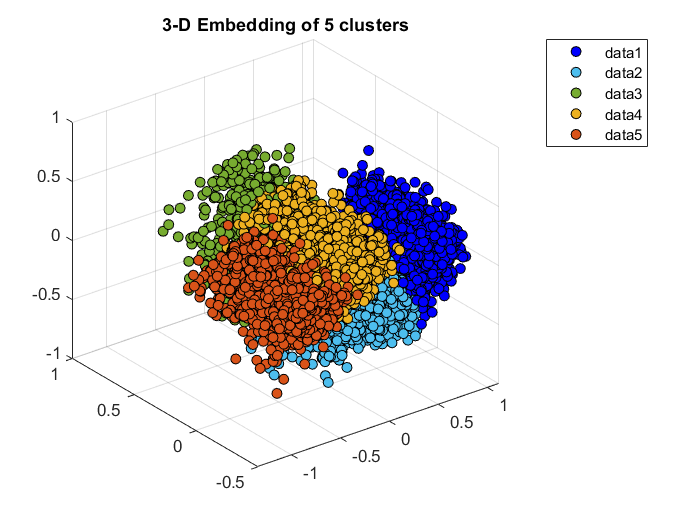


% K == 5 
rng('default')
[IDX5] = kmeans(X,5);

figure
scatter3(Y(IDX5==1,1),Y(IDX5==1,2),Y(IDX5==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(IDX5==2,1),Y(IDX5==2,2),Y(IDX5==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX5==3,1),Y(IDX5==3,2),Y(IDX5==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
scatter3(Y(IDX5==4,1),Y(IDX5==4,2),Y(IDX5==4,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.9290 0.6940 0.1250])
scatter3(Y(IDX5==5,1),Y(IDX5==5,2),Y(IDX5==5,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.8500 0.3250 0.0980])
title('3-D Embedding of 5 clusters')
hold off
legend

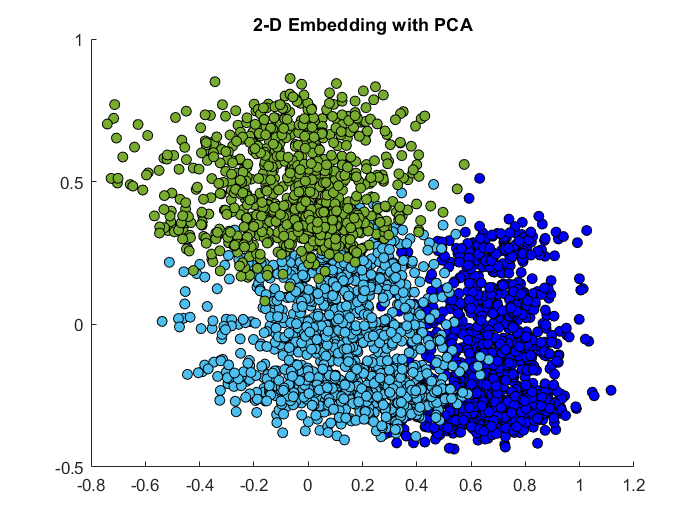


figure
scatter(Y(IDX5==1,1),Y(IDX5==1,2),...
'MarkerEdgeColor','k',...
'MarkerFaceColor',[0 0 1])
hold on
scatter(Y(IDX5==2,1),Y(IDX5==2,2),...
'MarkerEdgeColor','k',...
'MarkerFaceColor',[0.3010 0.7450 0.9330])
hold on 
scatter(Y(IDX5==3,1),Y(IDX5==3,2),...
'MarkerEdgeColor','k',...
'MarkerFaceColor',[0.4660 0.6740 0.1880])
title('2-D Embedding with PCA')

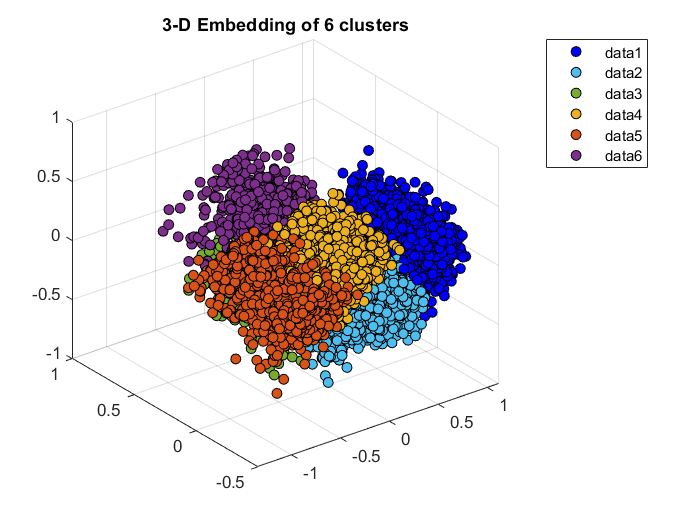


% K == 6
rng('default')
[IDX6] = kmeans(X,6);

figure
scatter3(Y(IDX6==1,1),Y(IDX6==1,2),Y(IDX6==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(IDX6==2,1),Y(IDX6==2,2),Y(IDX6==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX6==3,1),Y(IDX6==3,2),Y(IDX6==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
scatter3(Y(IDX6==4,1),Y(IDX6==4,2),Y(IDX6==4,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.9290 0.6940 0.1250])
scatter3(Y(IDX6==5,1),Y(IDX6==5,2),Y(IDX6==5,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.8500 0.3250 0.0980])
scatter3(Y(IDX6==6,1),Y(IDX6==6,2),Y(IDX6==6,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4940 0.1840 0.5560])
title('3-D Embedding of 6 clusters')
legend
hold off

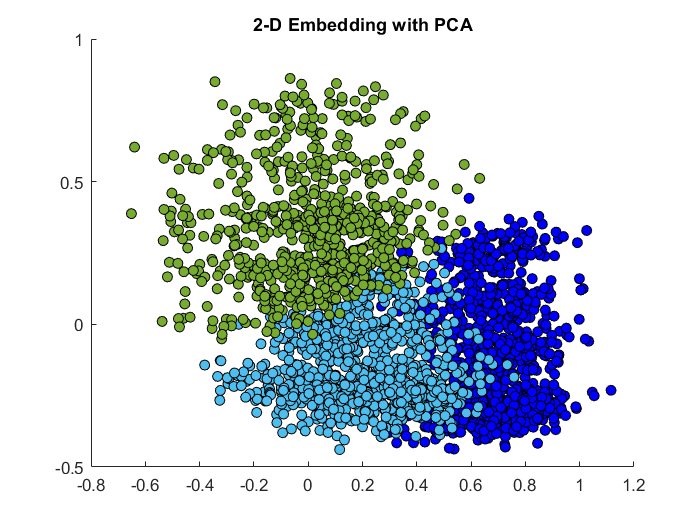


figure
scatter(Y(IDX6==1,1),Y(IDX6==1,2),...
'MarkerEdgeColor','k',...
'MarkerFaceColor',[0 0 1])
hold on
scatter(Y(IDX6==2,1),Y(IDX6==2,2),...
'MarkerEdgeColor','k',...
'MarkerFaceColor',[0.3010 0.7450 0.9330])
hold on 
scatter(Y(IDX6==3,1),Y(IDX6==3,2),...
'MarkerEdgeColor','k',...
'MarkerFaceColor',[0.4660 0.6740 0.1880])
title('2-D Embedding with PCA')

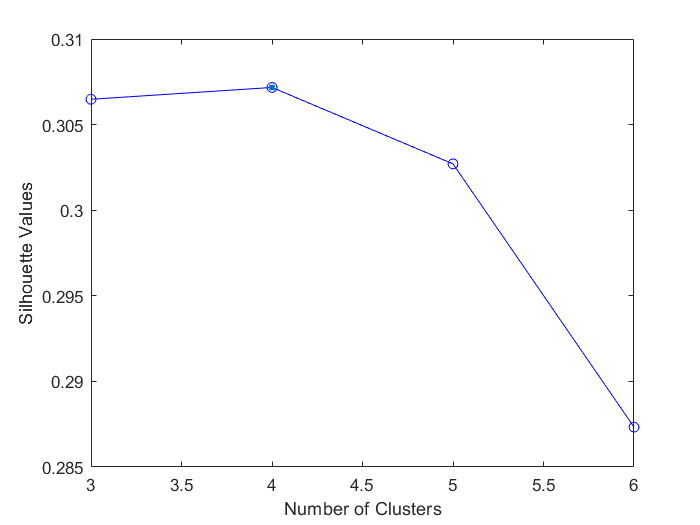


%% CLUSTERING EVALUATION (FITTING K)

% 3) Silhouette criterion
clust = [IDX3 IDX4 IDX5 IDX6];
eva = evalclusters(X,clust,'silhouette');
figure
plot(eva)

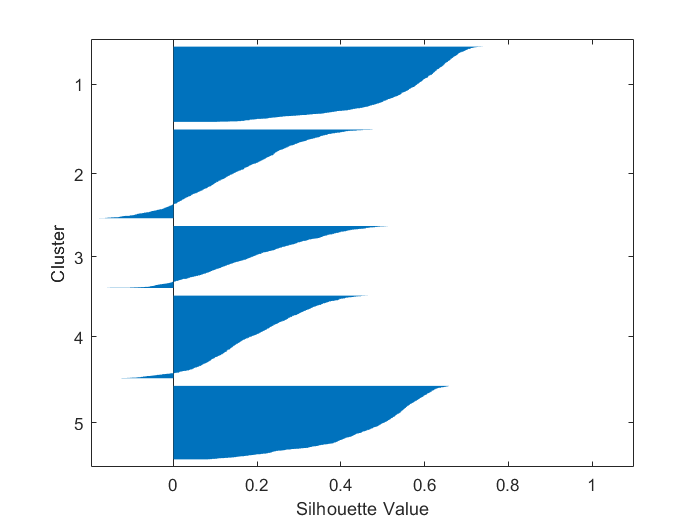


figure
silhouette(X,IDX5);

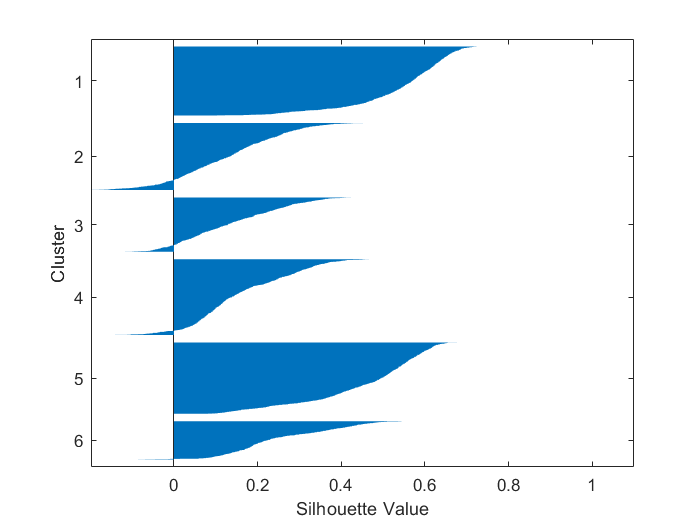

figure
silhouette(X,IDX6);


%% CLUSTER ANALYSIS

Xtot = BankClients;

X1 = Xtot((IDX4==1),:); %% no find
X2 = Xtot((IDX4==2),:);
X3 = Xtot((IDX4==3),:);
X4 = Xtot((IDX4==4),:);

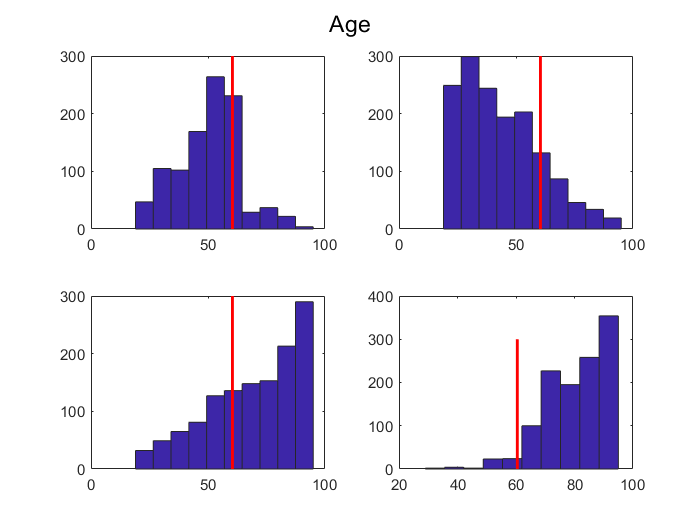

%% AGE
figure
temp = mean(BankClients.Age);
subplot(2,2,1)
hist(X1.Age)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,2)
hist(X2.Age)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,3)
hist(X3.Age)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,4)
hist(X4.Age)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
sgtitle('Age')

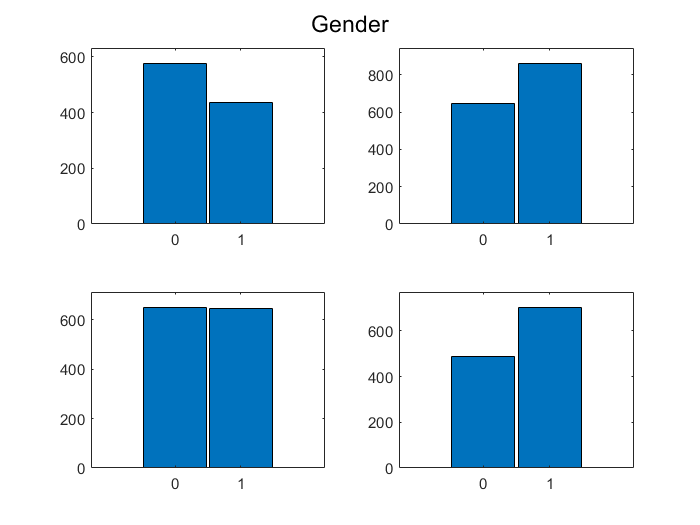

%% GENDER
figure
subplot(2,2,1)
hist(X1.Gender)
subplot(2,2,2)
hist(X2.Gender)
subplot(2,2,3)
hist(X3.Gender)
subplot(2,2,4)
hist(X4.Gender)
sgtitle('Gender')

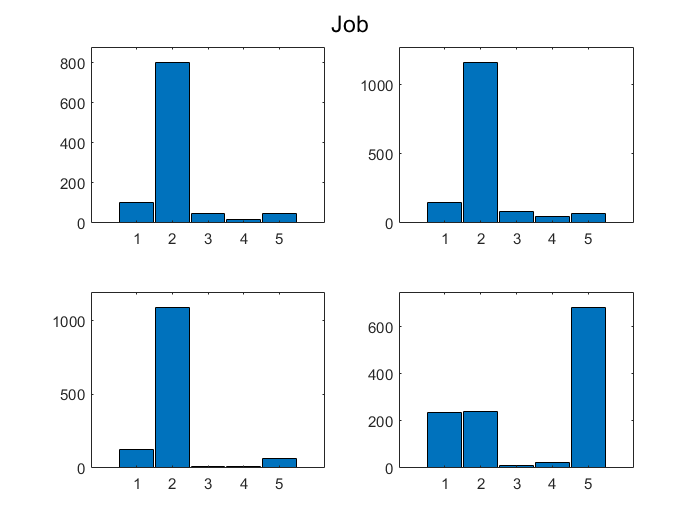

%% Job
figure
subplot(2,2,1)
hist(X1.Job)
subplot(2,2,2)
hist(X2.Job)
subplot(2,2,3)
hist(X3.Job)
subplot(2,2,4)
hist(X4.Job)
sgtitle('Job')

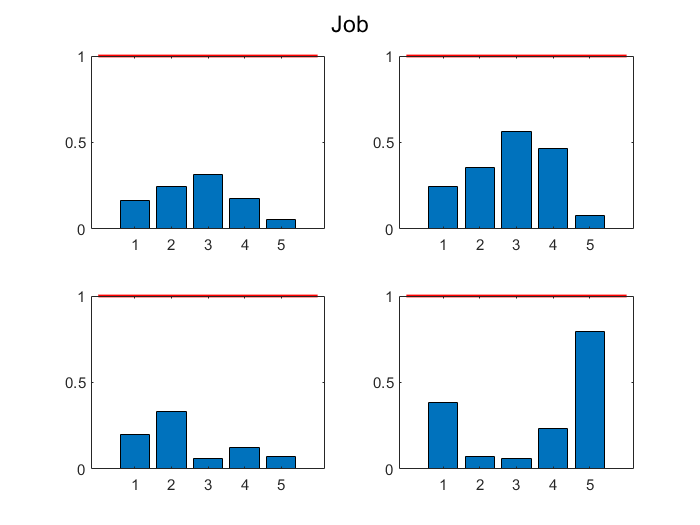

 counts = hist(Xtot.Job);
% 
ind1 = counts(1);
ind2 = counts(2);
ind3 = counts(3);
ind4 = counts(4);
ind5 = counts(5);
% 

ind = [ind1 ind2 ind3 ind4 ind5];

figure
subplot(2,2,1)
h1 = histogram(X1.Job);
h1 = h1.Values./ind;
h1 = bar(h1);
hold on
plot([0,6],[1,1],'r-','Linewidth',1.7)
subplot(2,2,2)

h2 = histogram(X2.Job);
h2 = h2.Values./ind;
h2 = bar(h2);
hold on
plot([0,6],[1,1],'r-','Linewidth',1.7)
subplot(2,2,3)

h3 = histogram(X3.Job);
h3 = h3.Values./ind;
h3 = bar(h3);
hold on
plot([0,6],[1,1],'r-','Linewidth',1.7)
subplot(2,2,4)

h4 = histogram(X4.Job);
h4 = h4.Values./ind;
h4 = bar(h4);
hold on
plot([0,6],[1,1],'r-','Linewidth',1.7)
sgtitle('Job')

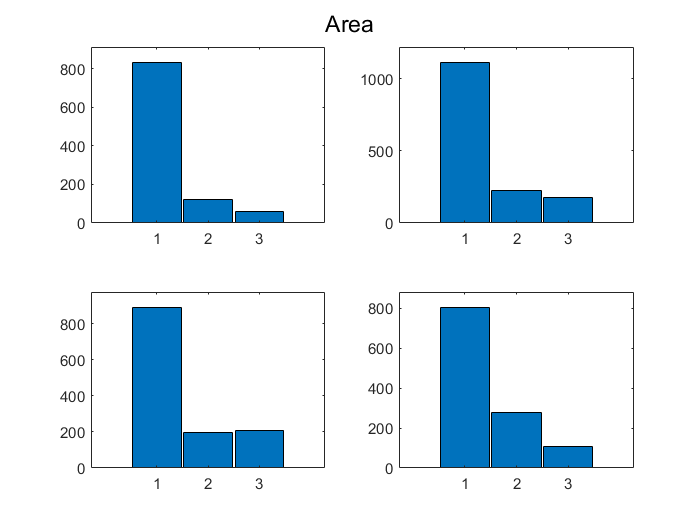

%% Area

figure
subplot(2,2,1)
hist(X1.Area)
subplot(2,2,2)
hist(X2.Area)
subplot(2,2,3)
hist(X3.Area)
subplot(2,2,4)
hist(X4.Area)
sgtitle('Area')

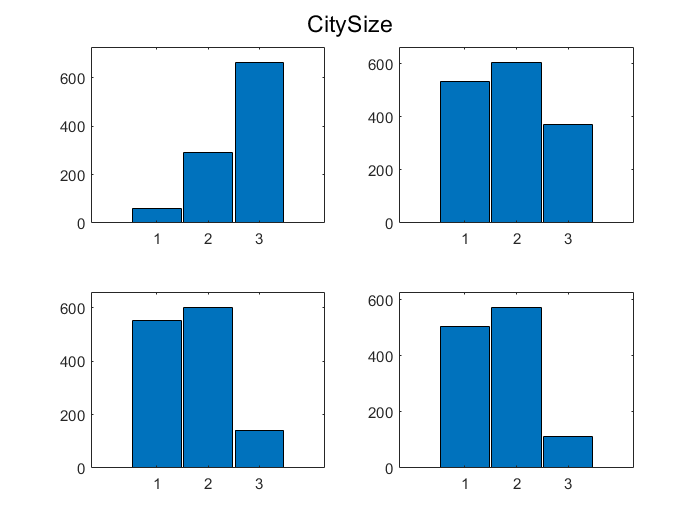

%% CitySize

figure
subplot(2,2,1)
hist(X1.CitySize)
subplot(2,2,2)
hist(X2.CitySize)
subplot(2,2,3)
hist(X3.CitySize)
subplot(2,2,4)
hist(X4.CitySize)
sgtitle('CitySize')

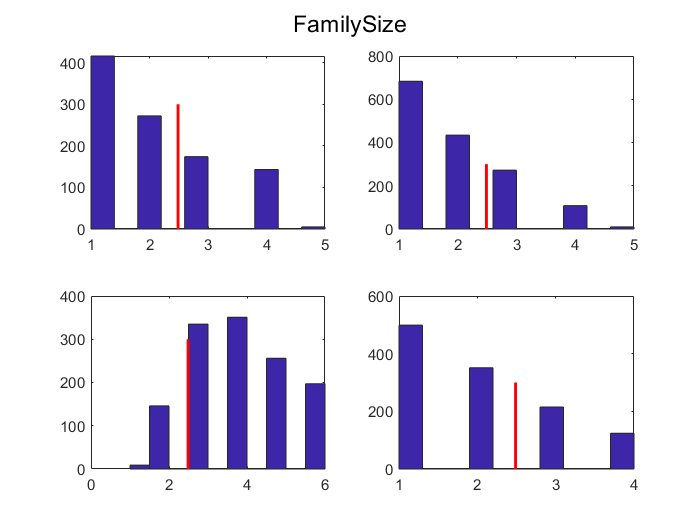

%% FamilySize

figure
temp = mean(BankClients.FamilySize);
subplot(2,2,1)
hist(X1.FamilySize)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,2)
hist(X2.FamilySize)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,3)
hist(X3.FamilySize)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,4)
hist(X4.FamilySize)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
sgtitle('FamilySize')

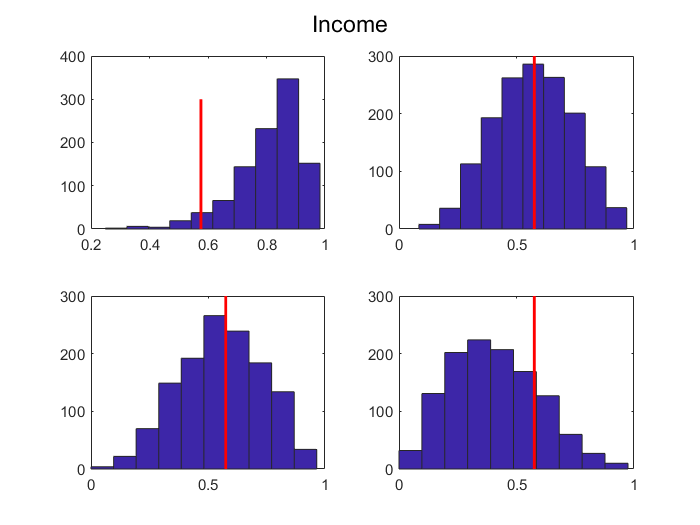

%% Income

figure
temp = mean(BankClients.Income);
subplot(2,2,1)
hist(X1.Income)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,2)
hist(X2.Income)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,3)
hist(X3.Income)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,4)
hist(X4.Income)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
sgtitle('Income')

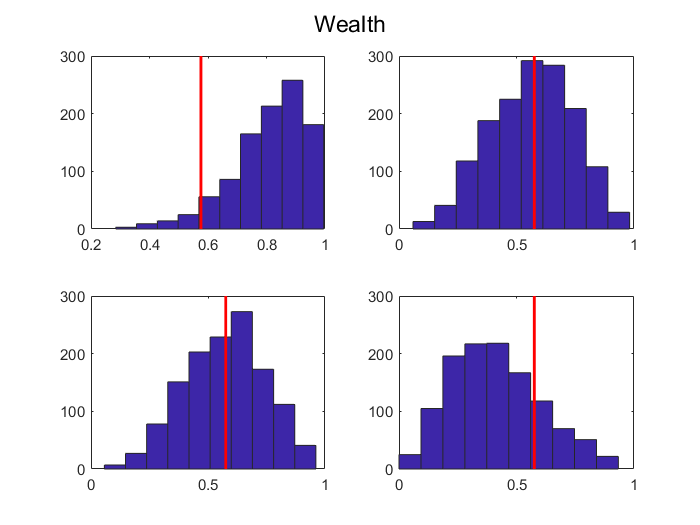

%% Wealth

figure
subplot(2,2,1)
hist(X1.Wealth)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,2)
hist(X2.Wealth)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,3)
hist(X3.Wealth)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,4)
hist(X4.Wealth)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
sgtitle('Wealth')

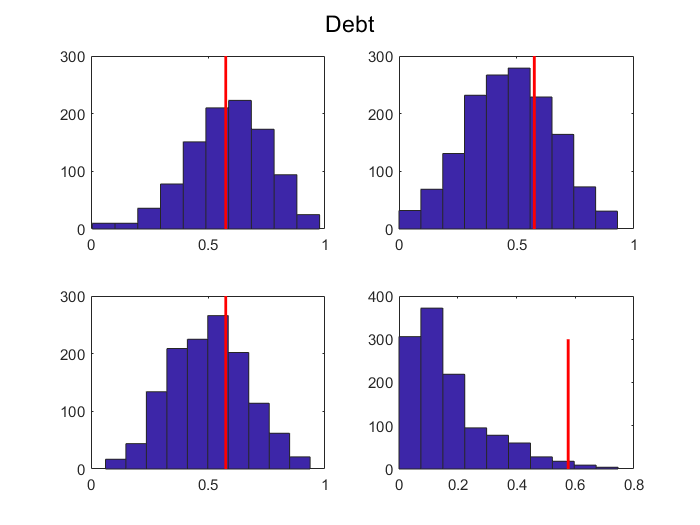

%% Debt
figure
subplot(2,2,1)
hist(X1.Debt)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,2)
hist(X2.Debt)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,3)
hist(X3.Debt)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,4)
hist(X4.Debt)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
sgtitle('Debt')

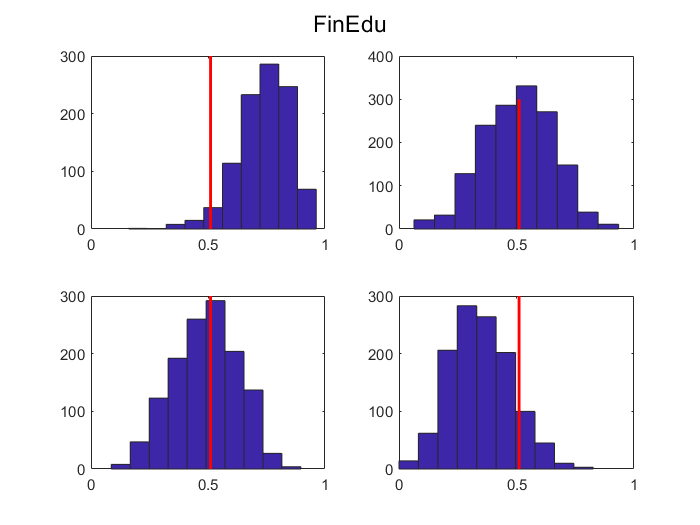

%% FinEdu

figure
temp = mean(BankClients.FinEdu);
subplot(2,2,1)
hist(X1.FinEdu)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,2)
hist(X2.FinEdu)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,3)
hist(X3.FinEdu)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,4)
hist(X4.FinEdu)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
sgtitle('FinEdu')

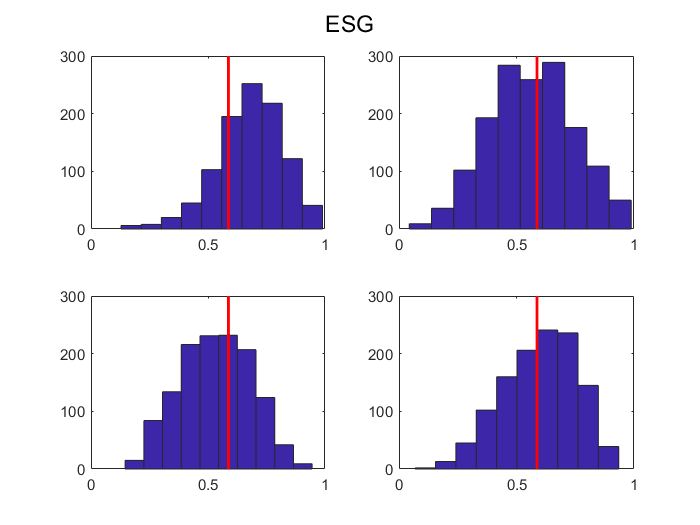

%% ESG
figure
temp = mean(BankClients.ESG);
subplot(2,2,1)
hist(X1.ESG)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,2)
hist(X2.ESG)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,3)
hist(X3.ESG)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,4)
hist(X4.ESG)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
sgtitle('ESG')

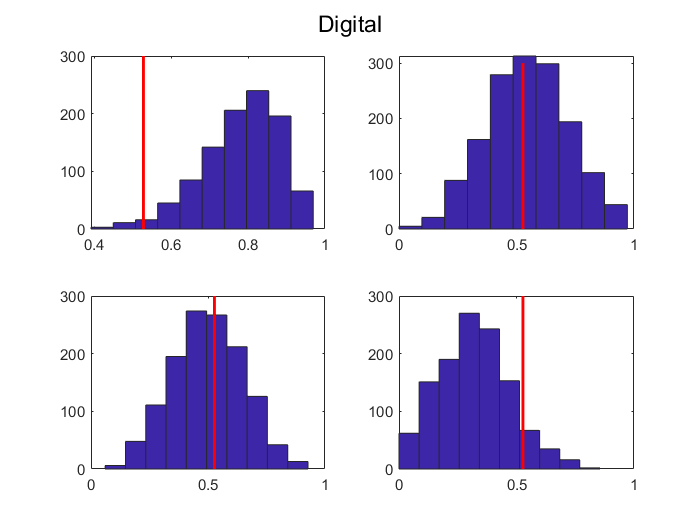

%% Digital
figure
temp = mean(BankClients.Digital);
subplot(2,2,1)
hist(X1.Digital)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,2)
hist(X2.Digital)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,3)
hist(X3.Digital)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,4)
hist(X4.Digital)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
sgtitle('Digital')

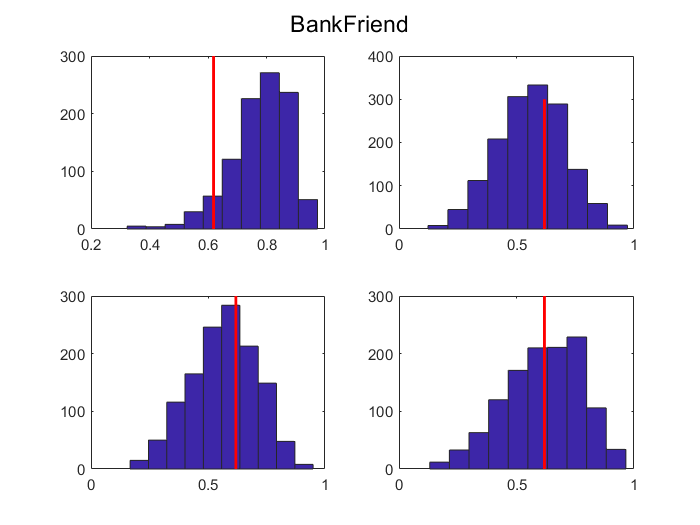

%% BankFriend
figure
temp = mean(BankClients.BankFriend);
subplot(2,2,1)
hist(X1.BankFriend)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,2)
hist(X2.BankFriend)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,3)
hist(X3.BankFriend)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,4)
hist(X4.BankFriend)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
sgtitle('BankFriend')

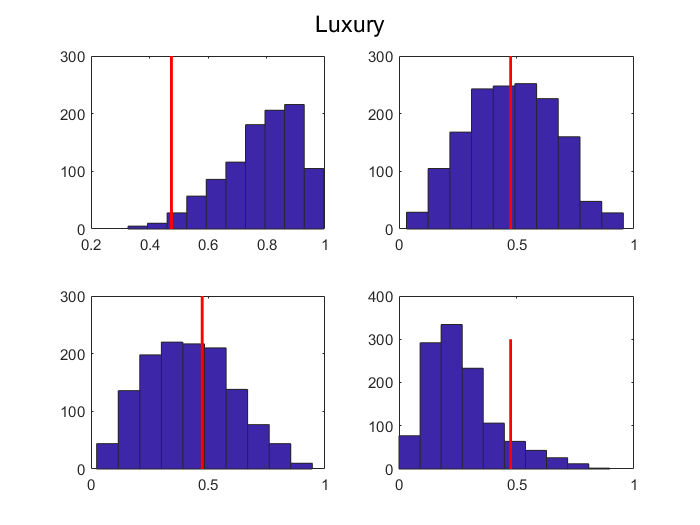

%% Lifestyle
figure
temp = mean(BankClients.Luxury);
subplot(2,2,1)
hist(X1.Luxury)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,2)
hist(X2.Luxury)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,3)
hist(X3.Luxury)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,4)
hist(X4.Luxury)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
sgtitle('Luxury')

%% Luxury
figure
temp = mean(BankClients.Luxury);
subplot(2,2,1)
hist(X1.Luxury)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,2)
hist(X2.Luxury)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,3)
hist(X3.Luxury)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,4)
hist(X4.Luxury)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
sgtitle('Luxury')

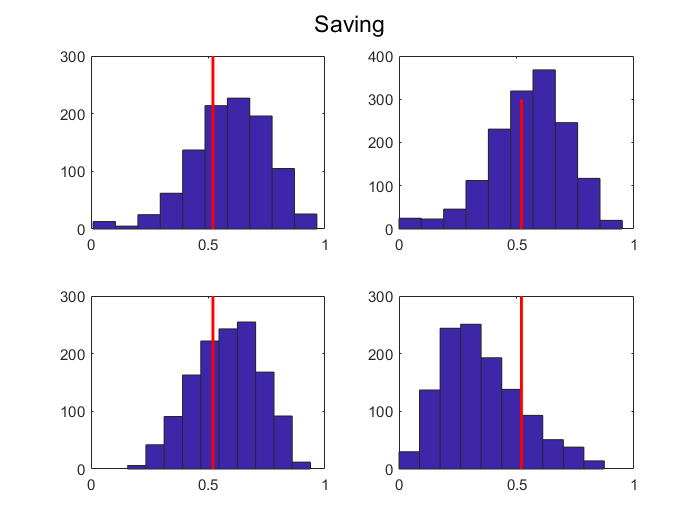

%% Savings
figure
temp = mean(BankClients.Saving);
subplot(2,2,1)
hist(X1.Saving)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,2)
hist(X2.Saving)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,3)
hist(X3.Saving)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
subplot(2,2,4)
hist(X4.Saving)
hold on
plot([temp,temp],[0,300],'r-','Linewidth',1.7)
sgtitle('Saving')

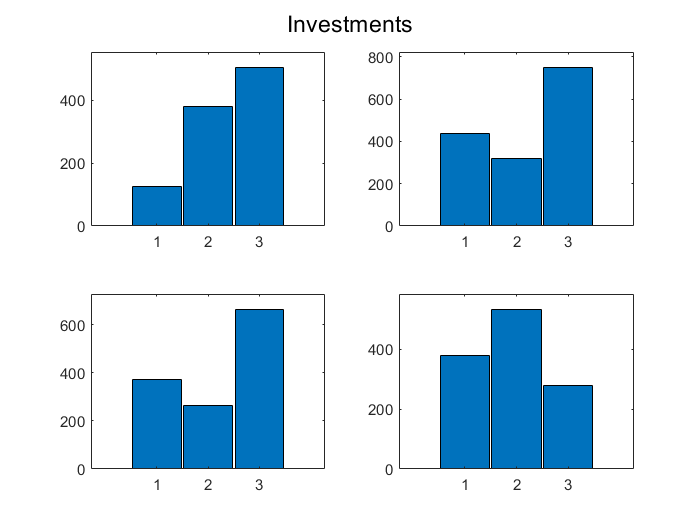

%%Investments
figure
subplot(2,2,1)
hist(X1.Investments)
subplot(2,2,2)
hist(X2.Investments)
subplot(2,2,3)
hist(X3.Investments)
subplot(2,2,4)
hist(X4.Investments)
sgtitle('Investments')